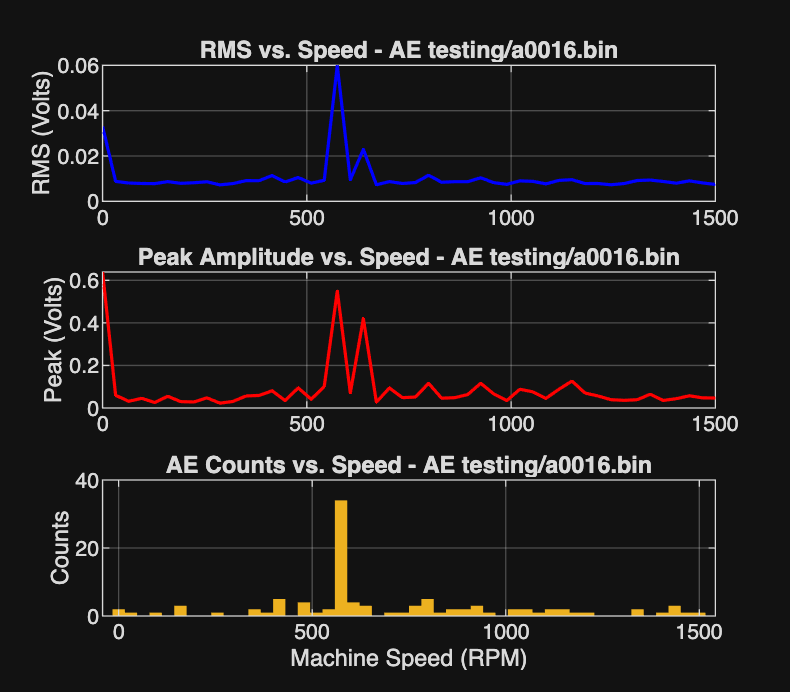

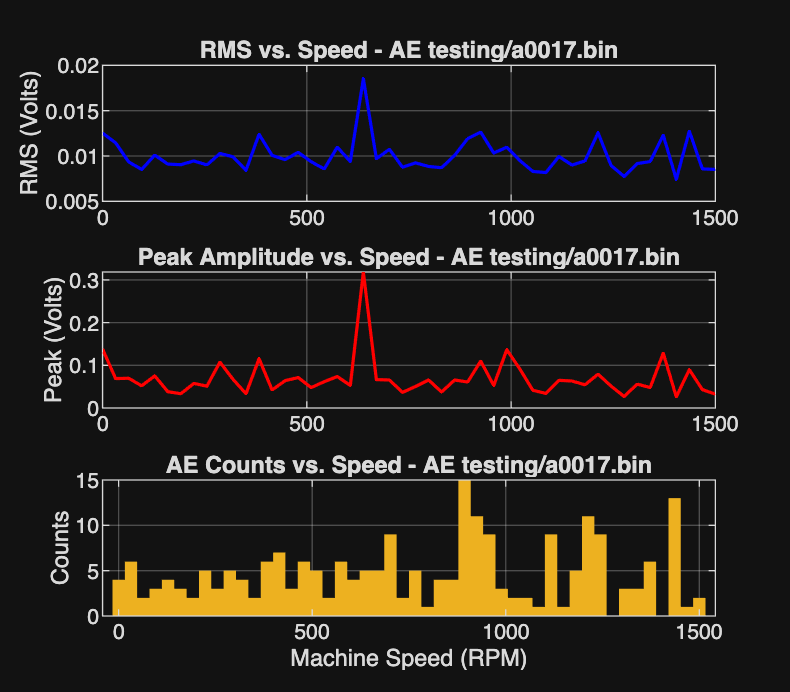

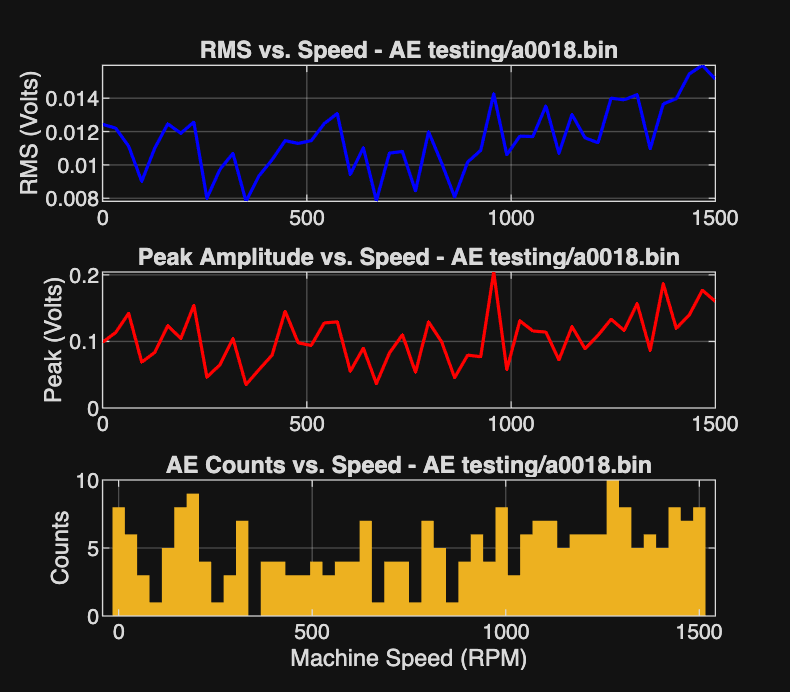

clear
clc
close all

%% 1. PARAMETERS & INITIALIZATION
fs = 4000;                % Sampling rate (Hz)
window_time = 0.1;        % 100 ms window
overlap = 0.0;            % 0% overlap 

% File definitions
files = [
    "AE testing/a0016.bin"
    "AE testing/a0017.bin"
    "AE testing/a0018.bin"
];

win = round(window_time * fs);           
step = round(win * (1 - overlap));       

%% 2. PIPELINE: SEPARATE EXTRACTION & VISUALIZATION PER FILE
for f = 1:length(files)
    filename = files(f);
    fid = fopen(filename, 'rb');
    
    if fid == -1
        fprintf("Cannot open file: %s. Check your current MATLAB directory.\n", filename);
        continue
    end

    % Read the 16-bit binary integer data
    data = fread(fid, Inf, 'uint16');
    fclose(fid);

    % Convert ADC integers to real Voltage
    signal = double(data) / 4096 * 3.3;   
    
    % Remove DC offset
    signal = signal - mean(signal);
    
    N = length(signal);
    
    % Define the Threshold for AE Counts
    Threshold = 3.0 * std(signal); 

    % Temporary arrays for the current file ONLY
    file_RMS = [];
    file_Peak = [];
    file_Counts = [];

    for i = 1:step:N-win
        segment = signal(i:i+win-1);
        
        % 1. RMS 
        val_rms = sqrt(mean(segment.^2));
        
        % 2. Peak Amplitude 
        val_peak = max(abs(segment));
        
        % 3. AE Counts 
        val_counts = sum(abs(segment) > Threshold);
        
        % Store features for this file
        file_RMS = [file_RMS; val_rms];
        file_Peak = [file_Peak; val_peak];
        file_Counts = [file_Counts; val_counts];
    end
    
    %% 3. SPEED SIMULATION & PLOTTING
    num_windows = length(file_RMS);
    
    % -------------------------------------------------------------
    % CREATING THE SPEED AXIS
    % Since your .bin files lack speed data, we simulate a run-up.
    % We assume the machine accelerates linearly from 0 to 1500 RPM.
    % -------------------------------------------------------------
    start_rpm = 0;
    end_rpm = 1500;
    speed_axis = linspace(start_rpm, end_rpm, num_windows);
    
    % Create a new figure window
    figure('Name', sprintf('Speed Analysis: %s', filename), 'Position', [50 + (f*50), 50 + (f*50), 800, 700]);
    
    % Plot 1: RMS vs Speed
    subplot(3, 1, 1);
    % Change the x-input from time_axis to speed_axis
    plot(speed_axis, file_RMS, 'b', 'LineWidth', 1.2);
    ylabel('RMS (Volts)');
    title(sprintf('RMS vs. Speed - %s', filename));
    grid on;
    
    % Plot 2: Peak Amplitude vs Speed
    subplot(3, 1, 2);
    plot(speed_axis, file_Peak, 'r', 'LineWidth', 1.2);
    ylabel('Peak (Volts)');
    title(sprintf('Peak Amplitude vs. Speed - %s', filename));
    grid on;
    
    % Plot 3: AE Counts vs Speed
    subplot(3, 1, 3);
    % We use 'bar' but adjust width so it renders nicely on a wider RPM scale
    bar(speed_axis, file_Counts, 'FaceColor', [0.9290, 0.6940, 0.1250], 'EdgeColor', 'none', 'BarWidth', 1);
    ylabel('Counts');
    % Update the x-axis label to reflect RPM
    xlabel('Machine Speed (RPM)'); 
    title(sprintf('AE Counts vs. Speed - %s', filename));
    grid on;
    
end